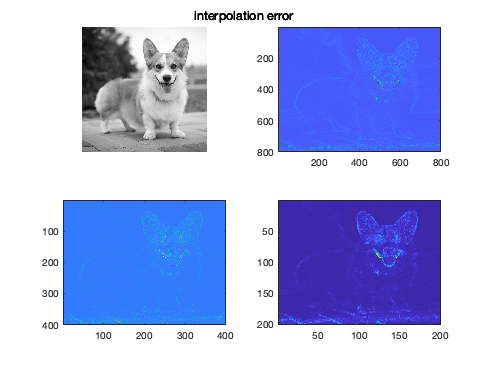

zs%%% 1. %%%
% Nc & Nr = 200
myIm = double(rgb2gray(imread('corgi-dog.jpg'))) / 255;
imshow(myIm);

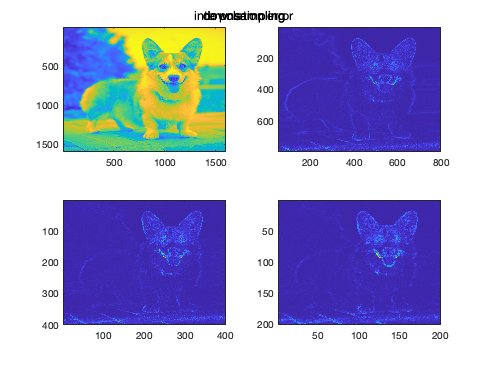


sampled = {myIm};
figure();
subplot(2, 2, 1);
imagesc(sampled{1});
for i = 2:4
    sampled{i} = sample(blur(sampled{i-1}, 0.4));
    subplot(2, 2, i);
    imagesc(sampled{i});
end
sgtitle('downsampling');

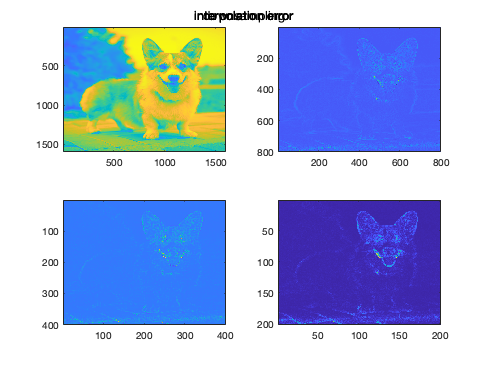



error = {};
figure();
subplot(2, 2, 4);
imagesc(sampled{4});
for i = 3:-1:1
    interp = interpolate(sampled{i+1});
    subplot(2, 2, i);
    error{i} = sampled{i} - interp;
    imagesc(error{i});
end
sgtitle('interpolation error');

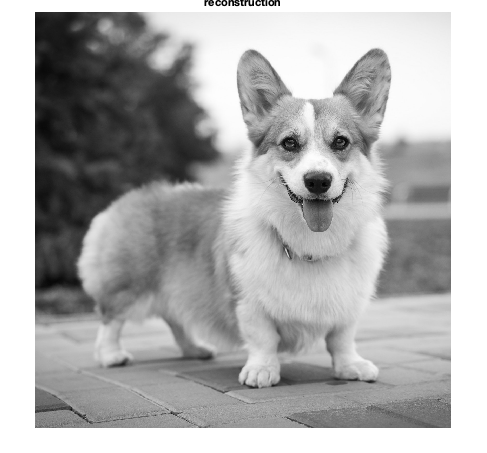


reconstruct = sampled{4};
for i = 3:-1:1
    reconstruct = interpolate(reconstruct) + error{i};
end
figure();
imshow(reconstruct);
title('reconstruction');

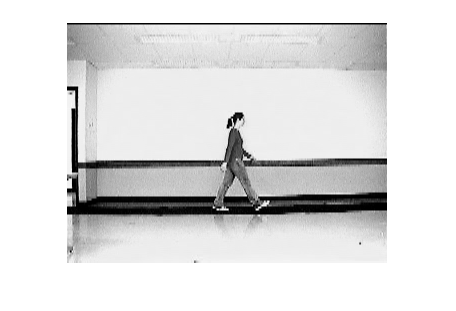

%%% 2. %%%
bg = double(imread(strcat('data/bg000.bmp'))) / 255;
obj = double(imread(strcat('data/walk.bmp'))) / 255;
diff = abs(obj - bg) > 0.25;
imshow(obj);

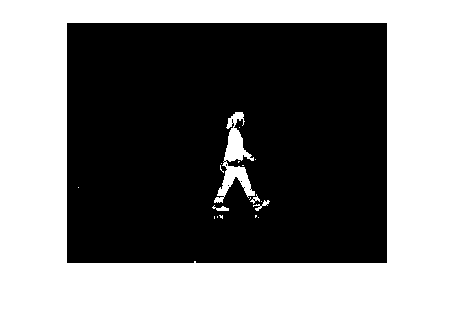

imshow(diff);

With a threshold of 0.25 I was able to get a pretty good image of the walking person. There were a few spots of noise, mostly because of the reflection of the person walking. In addition, I noticed that some parts of the persons body blended in very well with the background, so much so that they were not detected.

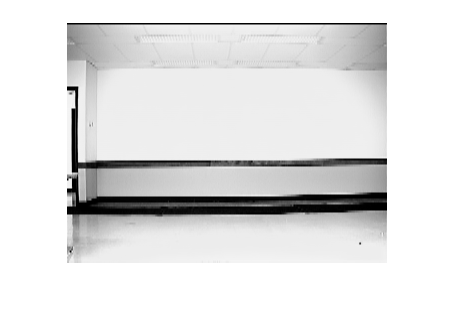

%%% 3 %%%%
bgVar = zeros(240, 320);
bgAvg = zeros(240, 320);

for f = dir('data/bg*')'
    bgAvg = bgAvg + double(imread(strcat('data/', f.name))) / 255;
end
bgAvg = bgAvg ./ length(dir('data/bg*'));

for f = dir('data/bg*')'
    bgVar = bgVar + ((double(imread(strcat('data/', f.name))) ./ 255) - bgAvg).^2;
end
bgVar = bgVar ./ length(dir('data/bg*'));
T = 18;
diff = ((obj - bgAvg).^2 ./ bgVar) > T^2;
imshow(bgAvg);

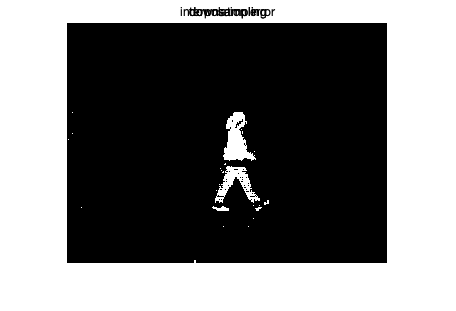

imshow(diff);

This method required much higher thresholds to get a good result. It was difficult for me to get a good separation of the object without removing too much of the outline of the person. I found that a threshold of 18 produced decent results. However, there were still many spots of noise and the figure almost completely lost their shoes. 

%%% 4. %%%
d_bsIm = bwmorph(diff, 'dilate');
imshow(d_bsIm);

Dilation greatly improved the results and brought back some form to the person, filling in some missing spots. However, the single pixels of noise scattered throughout the image became even larger.

%%% 5. %%%
[L, num] = bwlabel(d_bsIm, 8);
L = L == mode(L(L > 0));
imshow(L);

function [Gx, Gy] = gaussDeriv2D(sigma)
    x = 0:6*ceil(sigma);
    y = x';
    Gx = ((x-3*ceil(sigma))./(2*pi*sigma^4)).*(exp(-(((x-3*ceil(sigma)).^2+(y-3*ceil(sigma)).^2)./(2*sigma^2))));
    Gy = ((y-3*ceil(sigma))./(2*pi*sigma^4)).*(exp(-(((x-3*ceil(sigma)).^2+(y-3*ceil(sigma)).^2)./(2*sigma^2))));

end

function blurred = blur(im, a)
    [Gx, Gy] = gaussDeriv2D(a);
    gxIm = imfilter(im, Gx, 'replicate');
    gyIm = imfilter(im, Gy, 'replicate'); 
    blurred = sqrt(gxIm.^2 + gyIm.^2); 
end

function sampled = sample(im)
    [lx, ly] = size(im);
    sampled = zeros(int32(lx / 2), int32(ly / 2));
    for m = 1:2:lx
        for n = 1:2:ly
            sampled(ceil(double(m) / 2), ceil(double(n) / 2)) = im(m, n);
        end
    end
end

function interp = interpolate(im)
    [lx, ly] = size(im);
    interp = zeros(lx * 2 - 1, ly * 2 - 1);
    for x = 2:2:lx * 2 - 1
        interp(x - 1, 1:ly) = im(x / 2, :);
        interp(x + 1, 1:ly) = im(x / 2 + 1, :);
        interp(x, 1:ly) = (im(x / 2, :) + im(x / 2 + 1, :)) ./ 2;
    end

    for y = ly:-1:1
        interp(1:lx * 2 - 1, y * 2 - 1) = interp(1:lx * 2 - 1, y);
        if y ~= ly 
            interp(1:lx * 2 - 1, y * 2) = zeros(lx * 2 - 1, 1);
        end
    end

    for y = 2:2:ly * 2 - 1
        interp(:, y) = (interp(:, y - 1) + interp(:, y + 1)) ./ 2;
    end
end